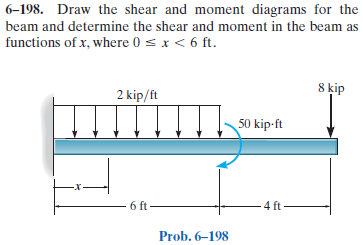

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-198RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-198RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R', 0);
b = b.add('reaction', 'moment', 'M', 0);
b = b.add('concentrated', 'moment', -50*u.kip*u.ft, 6*u.ft);
b = b.add('concentrated', 'force', -8*u.kip, 10*u.ft);
b = b.add('distributed', 'force', -2*u.kip/u.ft, [0 6]*u.ft);
b.L = 10*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x^{2}\,\left(x^{2}-40\,x\,\mathrm{ft}+996\,{\mathrm{ft}}^{2}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{4\,\left(-x^{3}+30\,x^{2}\,\mathrm{ft}+279\,x\,{\mathrm{ft}}^{2}-756\,{\mathrm{ft}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x^{2}-30\,x\,\mathrm{ft}+498\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{4\,\left(-x^{2}+20\,x\,\mathrm{ft}+93\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\left(x^{2}-20\,x\,\mathrm{ft}+166\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ 8\,\left(x-10\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -2\,\left(x-10\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ 8\,\mathrm{kip} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -2\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ 0 & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} M & 166\,\mathrm{ft}\,\mathrm{kip}\\ R & 20\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

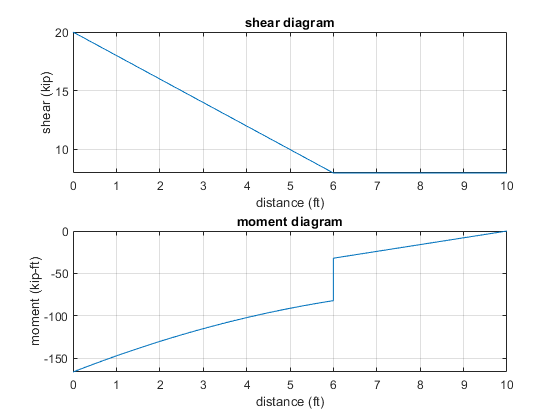

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;